# Burst & Bracketing Photography Example

Burst photography -- the combining of a burst of image captures to create a single output photograph -- has become common. Historically, the most common technique has been combining different exposure captures to allow for improved dynamic range. More recently, there has been a lot of interest in using captures with the same "under-exposure." This interest has been fueled by [Google's research into the topic](https://research.google/pubs/pub45586/).

In this Tutorial, we provide examples of combining multiple exposures of the same duration in ISETCam. Our initial examples are relatively simple because there is no motion in the scene. For general burst photography, objects (and the camera) move and the full algorithm has to include alignment code. So the last portion of the tutorial allows you to see the impact of both simple camera motion and a more complex subject motion in a burst of images.

History:

- Original Script, Wandell, 2019

- Livescript, burst comparisons, Bracketing, Motion, Cardinal, 2020

See also sensorComputeMEV, t_sensorMultipleExposure

ieInit
wbState = ieSessionGet('waitbar');
ieSessionSet('waitbar',false);  % Dealing with a waitbar/Matlab issue.

## Set up a scene and optical image (oi)

We can use an HDR scene or an RGB image. Using an HDR scene helps show the potential advantage of burst photography in capturing high-dynamic-range scenes by using multiple frames. Using an RGB image like the MCC provides a helpful tool in evaluating noise levels and image quality. 

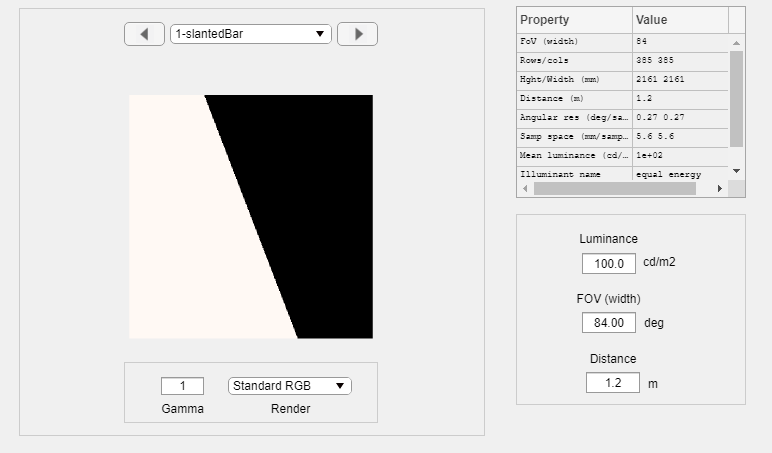

% Use the drop-down to pick the scene you want to use:
% * HDR scene provides best illustration of how
% bracketing and bursts can help with dynamic range.
% * Color Checker is great for evaluating noise
% * Slanted Edge makes it easy to visualize motion artifacts
sceneChoice = "SE";
switch sceneChoice
    case "HDR"
        scene = sceneFromFile('Feng_Office-hdrs.mat','multispectral'); %#ok<NASGU> 
        hdrScene = true;
    case "MCC"
        scene = sceneCreate; %#ok<NASGU> 
        hdrScene = false;
    case "SE"
        scene = sceneCreate('slanted edge'); %#ok<NASGU> 
        hdrScene = false;
end
if hdrScene
    scene = sceneFromFile('Feng_Office-hdrs.mat','multispectral'); 
end

% setting FOV larger by default also increases resolution, but slows
% things down
scene = sceneSet(scene, 'fov', 84); % FOV of many smartphones, like Google Pixel 4a
sceneWindow(scene); 

if hdrScene
    % can't set this until the scene is open
    sceneSet(scene,'display mode','hdr');
end
% create an optical image of our scene with the default optics
oi = oiCreate; oi = oiCompute(oi,scene);

## Run the sensor simulations

### First in auto exposure mode.  

This works okay for the MCC, but not so well for the HDR scene, as the sensor can't capture the full range of the scene at once.

% Create a default sensor and set it to our scene FOV
sensor = sensorCreate; 
sensor = sensorSet(sensor,'fov',sceneGet(scene,'fov'),oi);

sensorAE = sensorSet(sensor,'name','Single-frame, Auto exposure');
sensorAE = sensorSet(sensorAE,'noise flag','default'); 
sensorAE = sensorCompute(sensorAE,oi);

Line is (x,y), not row,col.  (1,1) is upper left corner. 

The bright region is the window in the image.

% Select a line (fraction from top of scene) to evaluate
showHLine      = 0.531

showHLine = 0.5310

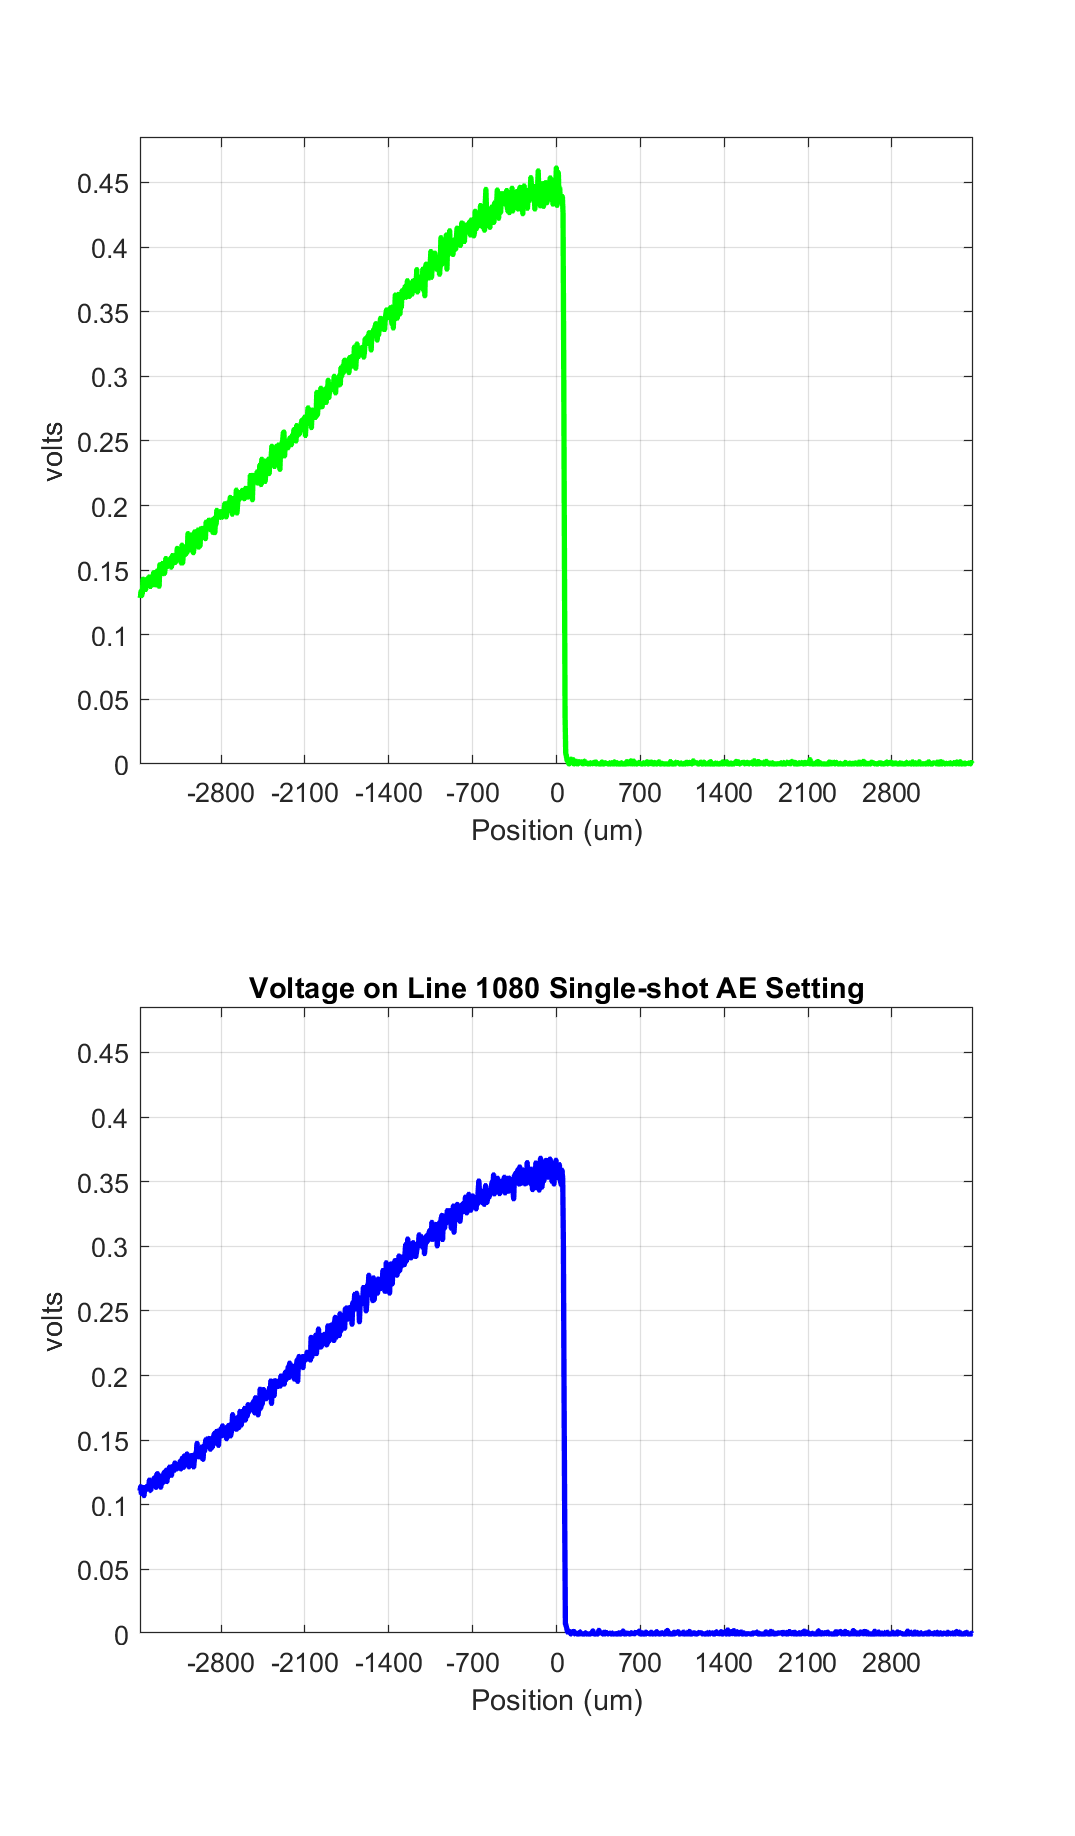

showLine = round(showHLine * sensorGet(sensor,'row'));
sensorPlot(sensorAE,'volts hline',[1,showLine]);
title(['Voltage on Line ', num2str(showLine), ' Single-shot AE Setting']);

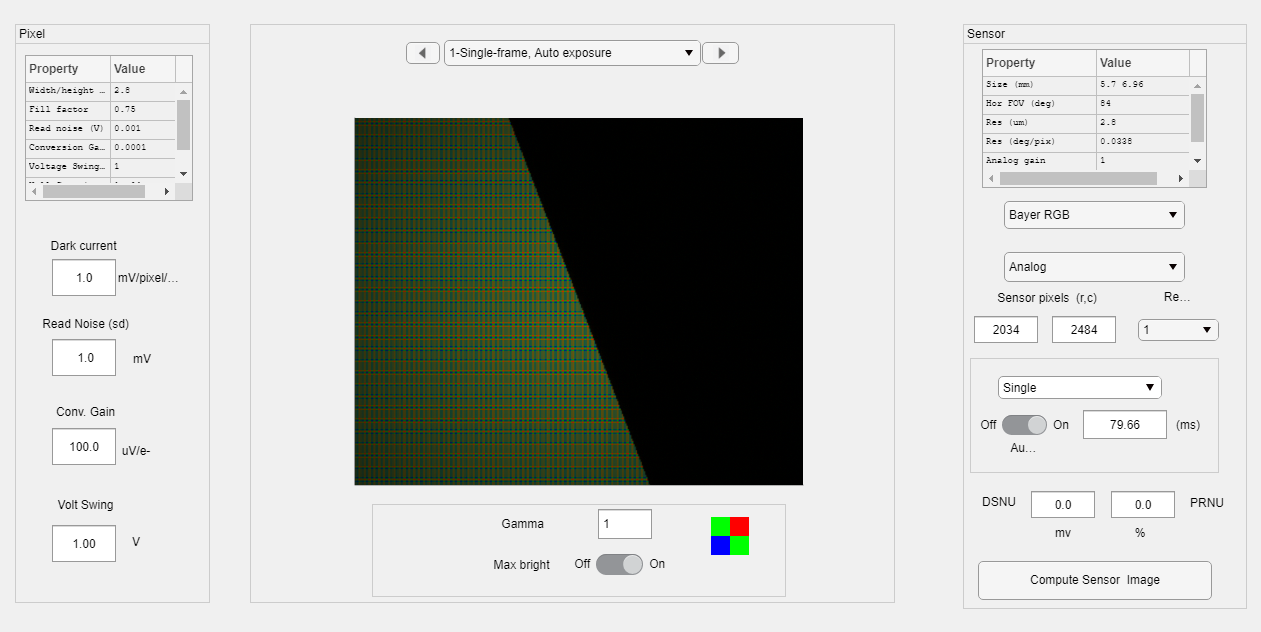

sensorWindow(sensorAE);


% we do this after the AE version to change the burst gamma?
%sensorSet(sensor,'gamma',0.3);

### Now operate the sensor in burst mode

We'll experiment with the default noise setting, and then turn off all the sensor noise.

Use the slider to control how many images to take in a burst.

numImages     = 8 % Select # of images in a burst

numImages = 8

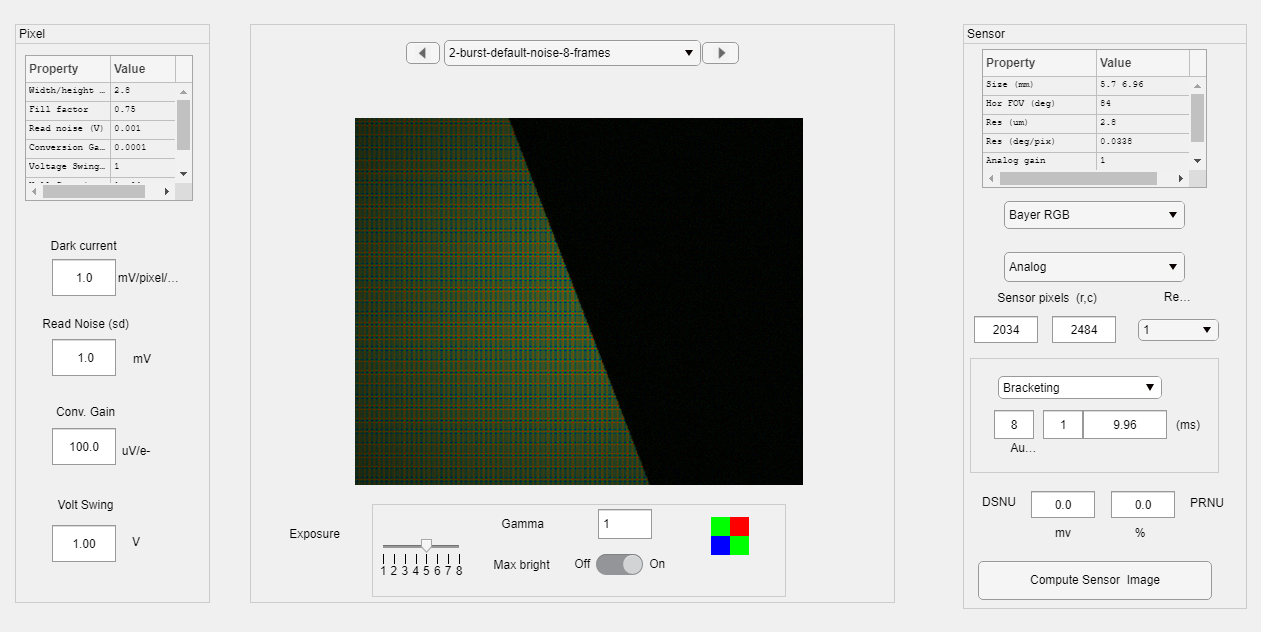

% Set exposure time so sum of the burst images gives us a total
% exposure time equal to the Auto-Exposure calculation:
expTime     = autoExposure(oi,sensor)/numImages; 
burstTiming = repmat(expTime,1,numImages);

sensorBurst = sensorSet(sensor,'exp time',burstTiming);
sensorBurst = sensorSet(sensorBurst,'exposure method', 'burst');

sensorBurst = sensorSet(sensorBurst,'noise flag','default'); 
sensorBurst = sensorSet(sensorBurst,'name',sprintf('burst-default-noise-%d-frames',numel(burstTiming)));
sensorBurst = sensorCompute(sensorBurst,oi);
% Now we can see each of the burst of captures separately:
sensorWindow(sensorBurst);

% v = sensorGet(sensorBurst,'volts');
% ieNewGraphWin; plot(squeeze(v(134,:,3)));

### Now build a low-noise version of the sensor:

sensorBurstLN = sensorSet(sensor,'exp time',burstTiming);
sensorBurstLN = sensorSet(sensorBurstLN,'exposure method', 'burst');
sensorBurstLN = sensorSet(sensorBurstLN,'noise flag','none'); % turn sensor noise off
sensorBurstLN = sensorSet(sensorBurstLN,'name',sprintf('burst-low-noise-%d-frames',numel(burstTiming)));
sensorBurstLN = sensorCompute(sensorBurstLN, oi);
% Now we can see each of the burst of captures separately:
sensorWindow(sensorBurstLN);

### Calculate the combined images for our burst sensors:

Currently we simply sum the voltage from each image capture of our default noise and low-noise burst sensors to get our total exposure time (by default equal to a single AE frame):

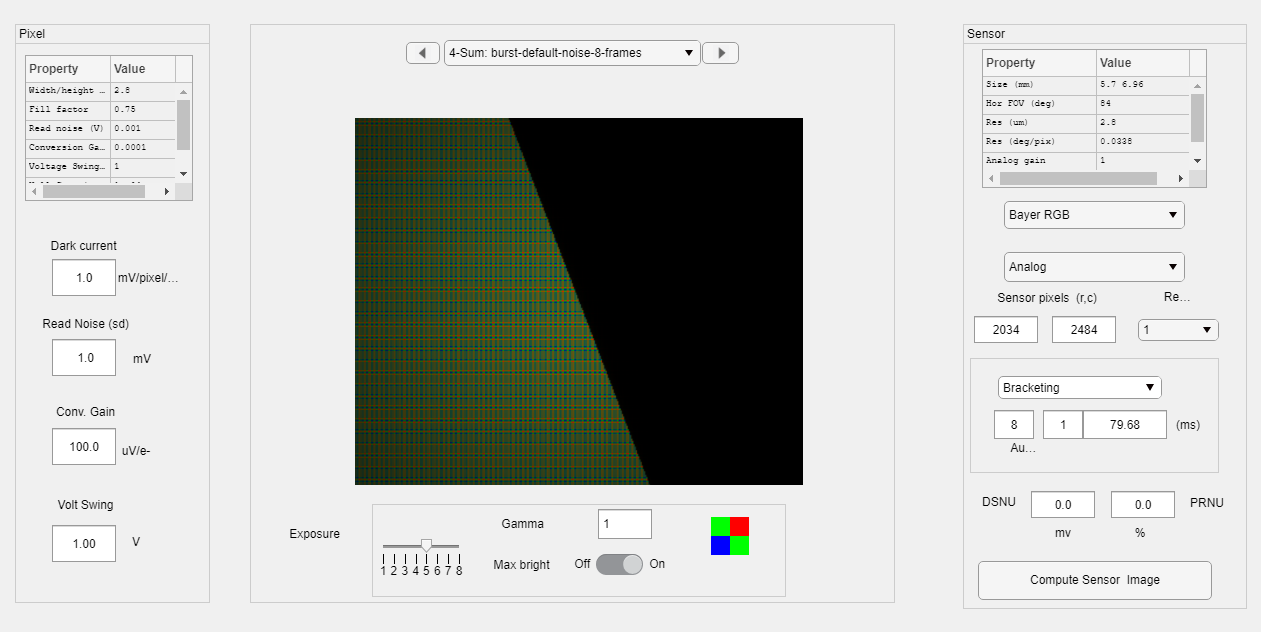

% Now that we have IP support for Burst, maybe we can
% re-write to use ip to calculate the sum?
voltsBurst = sensorGet(sensorBurst, 'volts');
voltsBurst = sum(voltsBurst,3);
% By adding up the bursts, we effectively have only 1 exp time
sensorBurstSum = sensorSet(sensorBurst,'volts',voltsBurst);
sensorBurstSum = sensorSet(sensorBurstSum,'exp time',burstTiming(1)*numImages); 
sensorBurstSum = sensorSet(sensorBurstSum,'name',sprintf('Sum: burst-default-noise-%d-frames',numel(burstTiming)));
sensorWindow(sensorBurstSum);

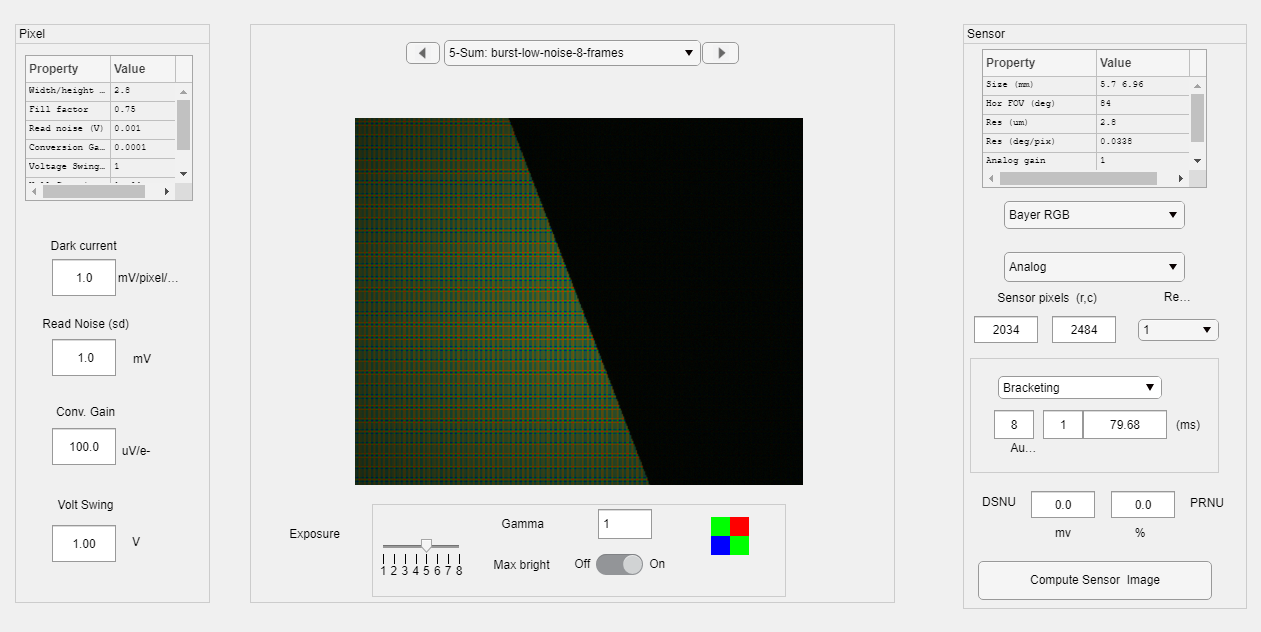

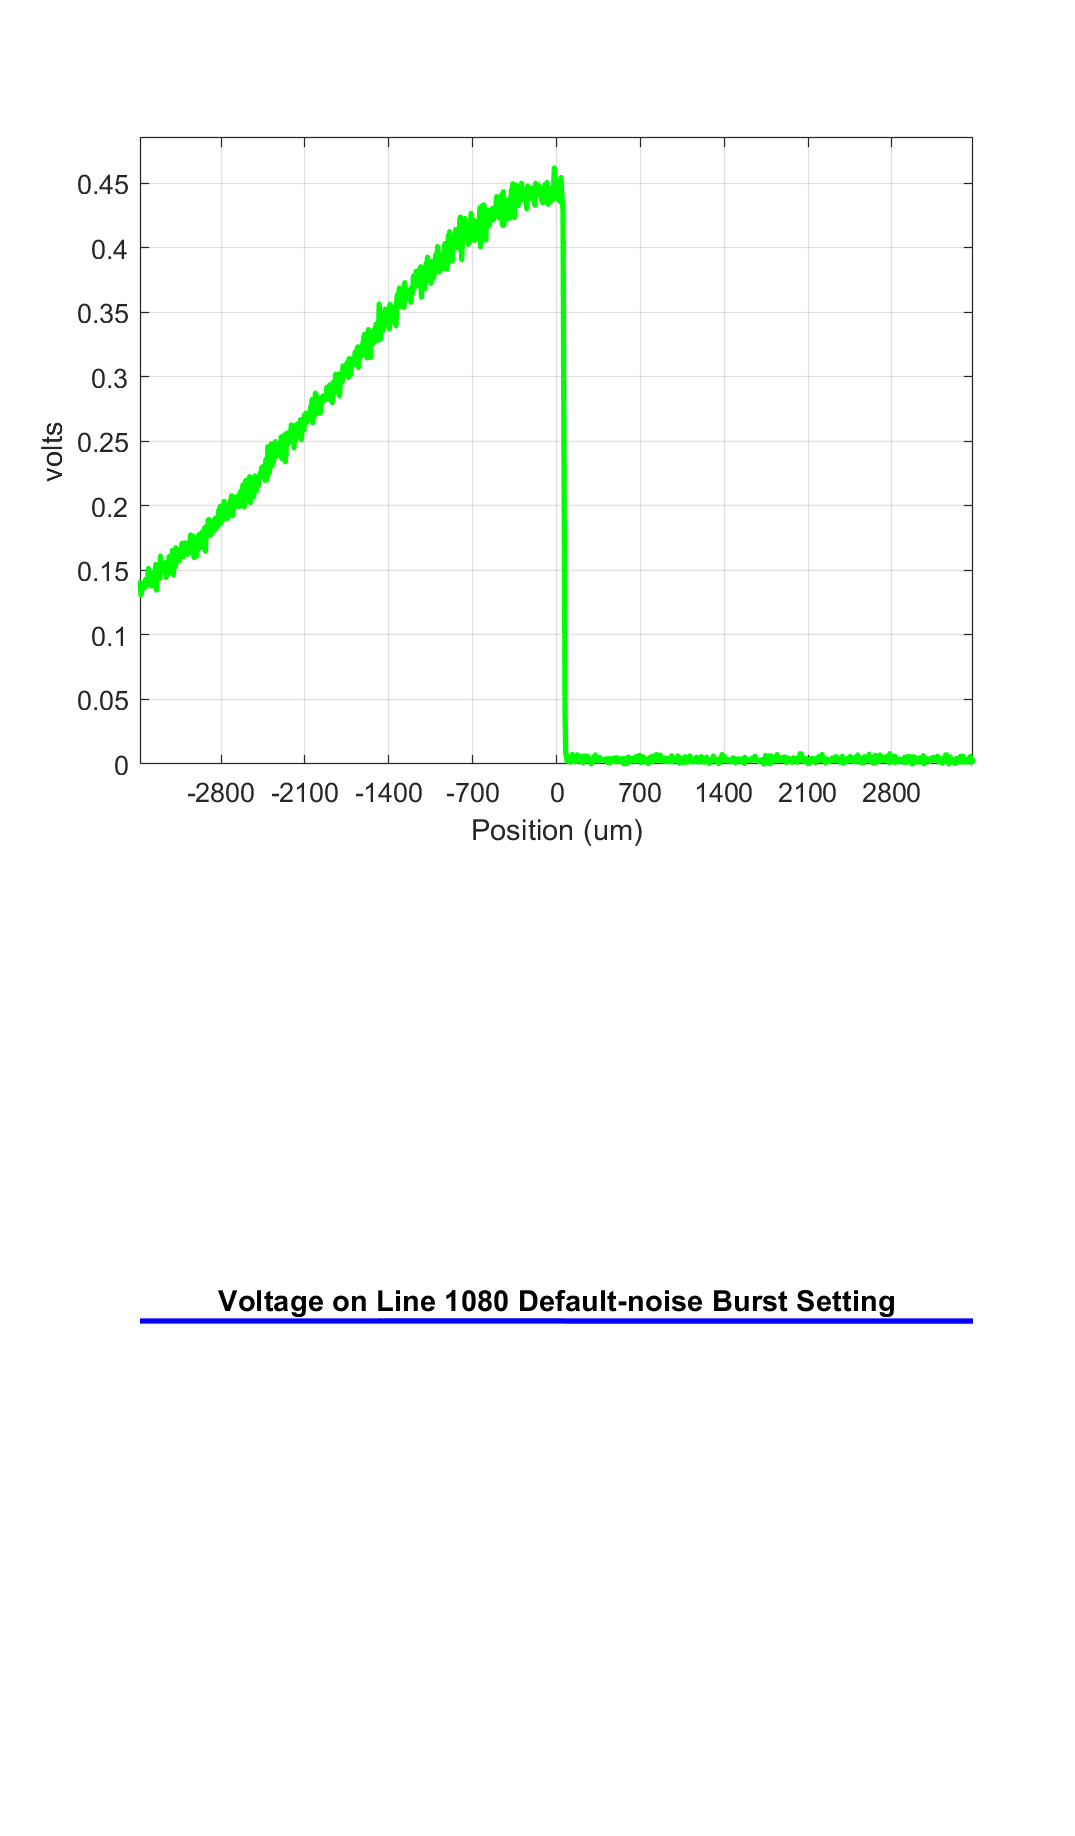

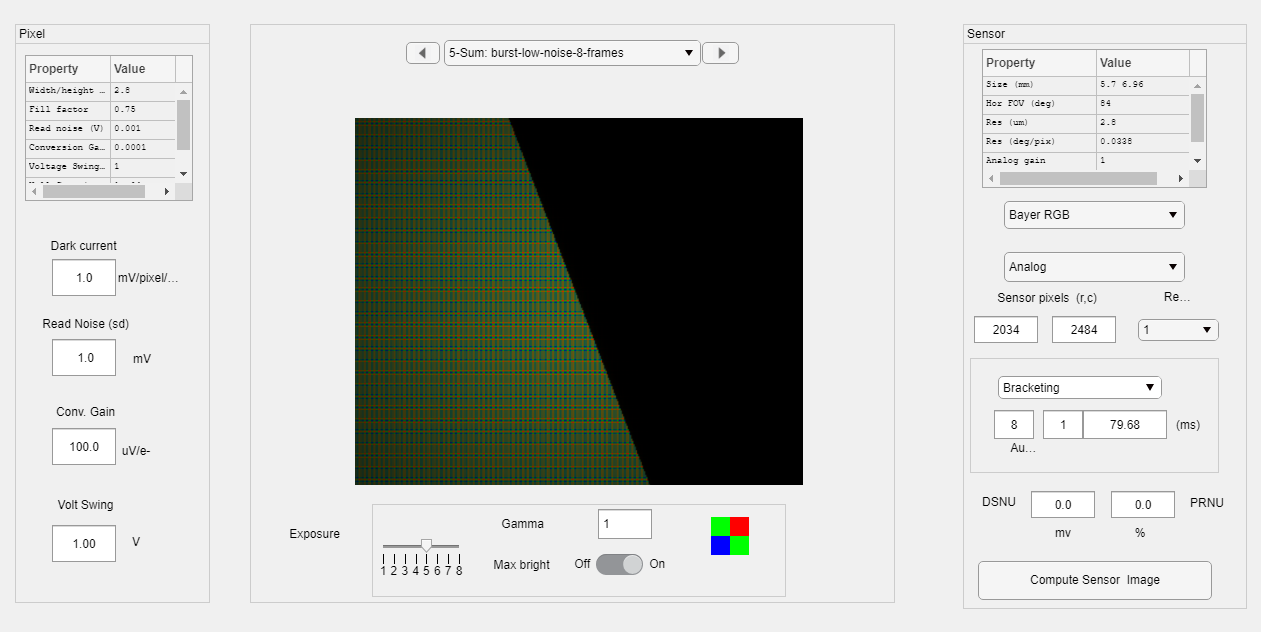


% Line is (x,y), not row,col.  (1,1) is upper left corner.
sensorPlot(sensorBurstSum,'volts hline',[1,showLine]);
title(['Voltage on Line ', num2str(showLine), ' Default-noise Burst Setting']);

voltsLN = sensorGet(sensorBurstLN,'volts');
voltsLN = sum(voltsLN,3);
sensorBurstLNSum = sensorSet(sensorBurstLN,'volts',voltsLN);
sensorBurstLNSum = sensorSet(sensorBurstLNSum,'exp time',burstTiming(1)*numImages); 
sensorBurstLNSum = sensorSet(sensorBurstLNSum,'name',sprintf('Sum: burst-low-noise-%d-frames',numel(burstTiming)));

sensorWindow(sensorBurstLNSum);

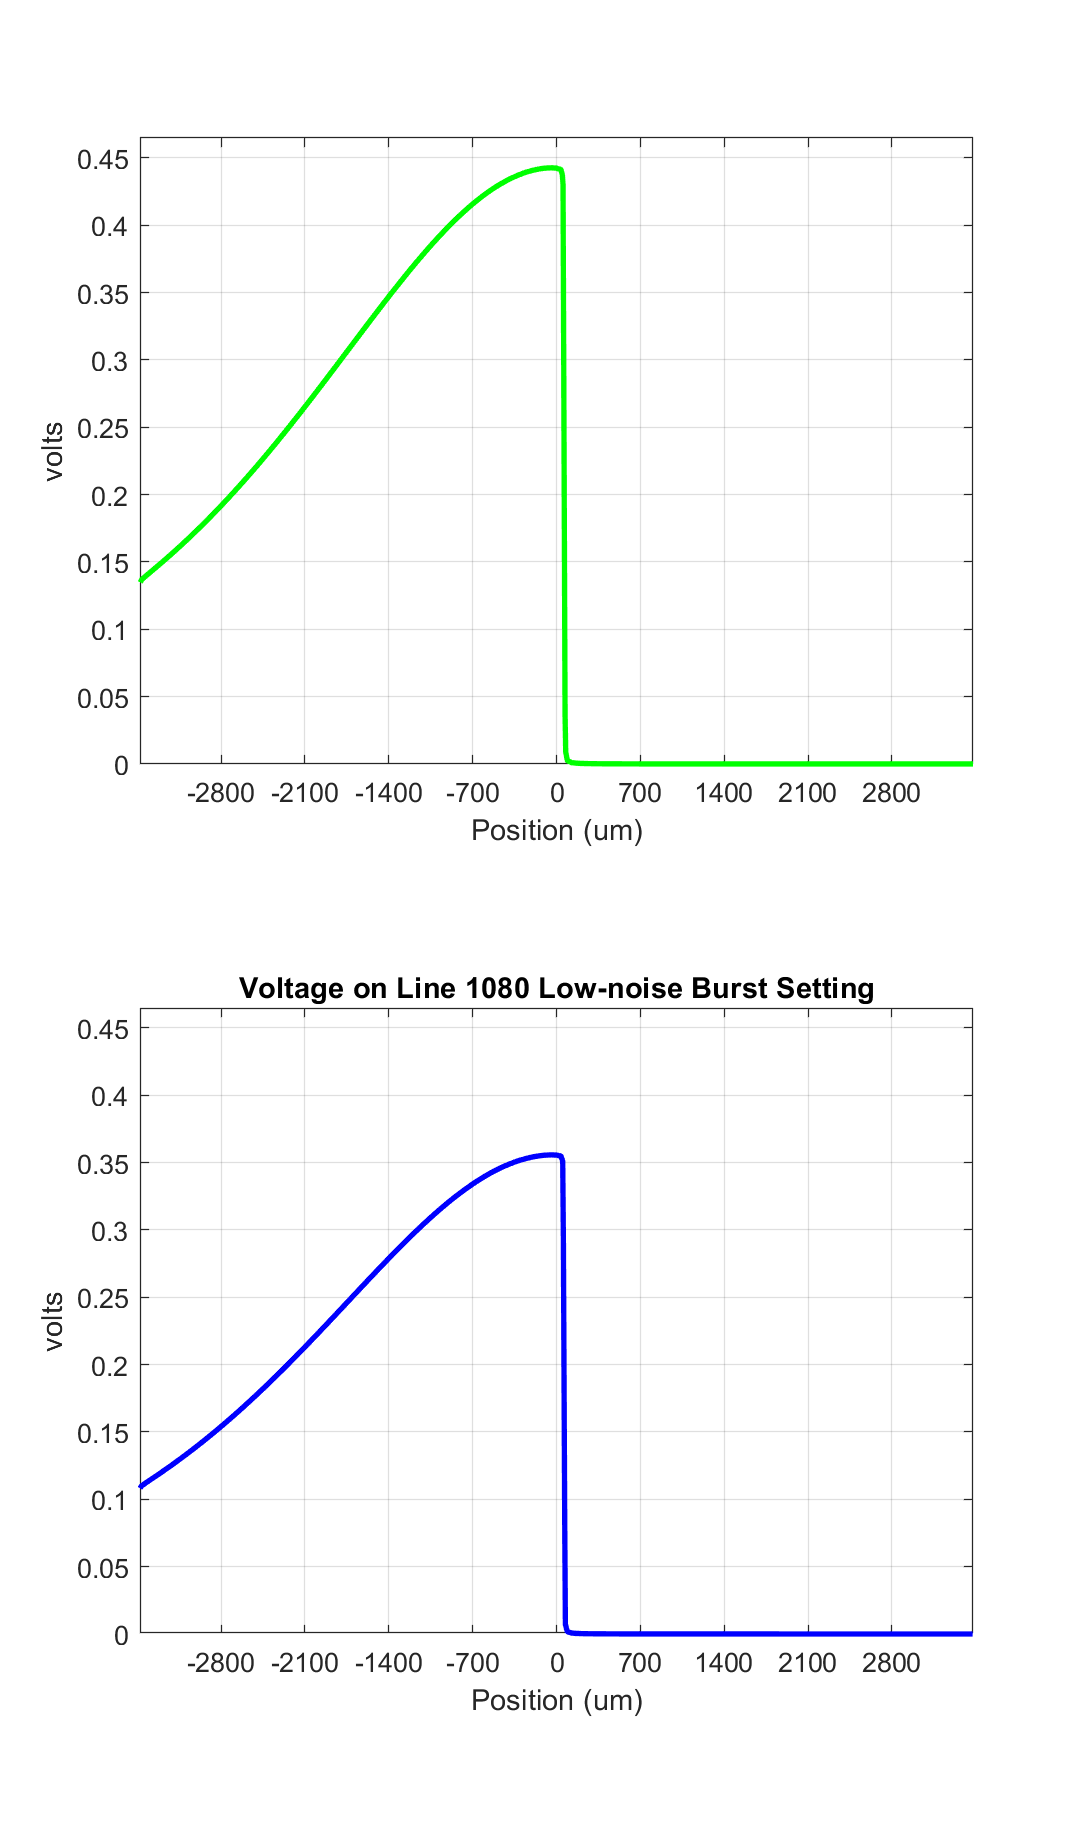


% Line is (x,y), not row,col.  (1,1) is upper left corner.
sensorPlot(sensorBurstLNSum,'volts hline',[1,showLine]);
title(['Voltage on Line ', num2str(showLine), ' Low-noise Burst Setting']);

### Process our Images

We use the same imaging pipeline (ip) for all three sensor versions (single-shot AE, Default-noise model Burst, and Low-Noise Burst). Note that because this is a Live Script, the graphs and thumbnails of the full Windows will show up on the right, with the interactive Windows being displayed separately.

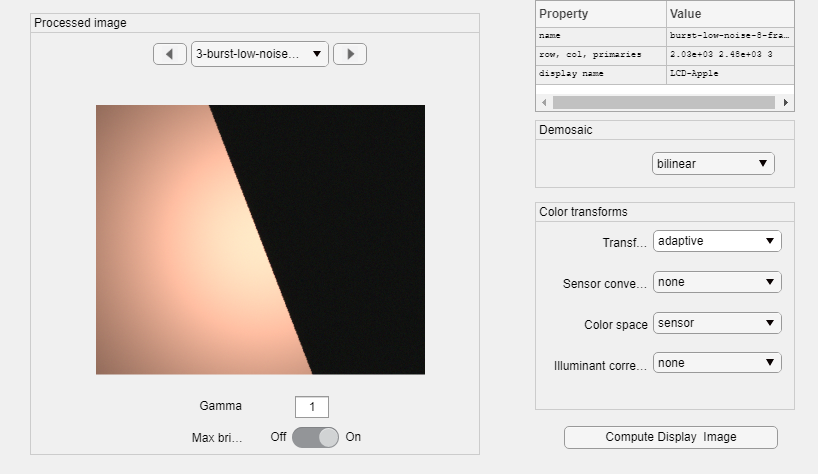

ip = ipCreate;
ip = ipSet(ip, 'render demosaic only', 'true');
ip = ipCompute(ip, sensorAE);
if hdrScene
    rgb = ipGet(ip, 'srgb');
    rgb = hdrRender(rgb);
    aeWin = ieNewGraphWin;
    aeWin.Name = 'AE Single Exposure';
    fprintf("AE Single Exposure\n");
    imagescRGB(rgb);
end
ipWindow(ip); 

ipBurst  = ipCreate;
ipBurst = ipSet(ipBurst, 'render demosaic only', 'true');

ipBurst = ipSet(ipBurst, 'combinationMethod', 'sum');
ipBurst  = ipCompute(ipBurst,sensorBurst);
if hdrScene
    rgbBurst = ipGet(ipBurst,'srgb');
    rgbBurst = hdrRender(rgbBurst);
    burstWin = ieNewGraphWin;
    burstWin.Name = 'Burst with Default Noise';
    fprintf("Burst with Default Noise\n");
    imagescRGB(rgbBurst);
end
ipWindow(ipBurst);  

ipLN  = ipCreate;
ipLN = ipSet(ipLN, 'render demosaic only', 'true');
ipLN = ipSet(ipLN, 'combinationMethod', 'sum');
ipLN  = ipCompute(ipLN,sensorBurstLN);
if hdrScene
    rgbLN = ipGet(ipLN,'srgb');
    rgbLN = hdrRender(rgbLN);
    lnWin = ieNewGraphWin;
    lnWin.Name = 'Burst with Low Noise';
    fprintf("Burst with Low Noise\n");
    imagescRGB(rgbLN);
end
ipWindow(ipLN);  

## Experiment with Bracketing Exposures

Traditional "HDR" photography typically involves capturing a sequence of imges using exposures both below and above the normal "AutoExposure" value. Those images can be combined in camera or in post processing using a variety of algorithms to achieve the desired result.

The simplest way to combine the images -- that we use here -- is to use the largest non-saturated value at each pixel to create the finished photo. Intuitively you might think that more images and a wider range of bracketing are always better. However, depending on the quality of the sensor in use, noise can become an issue.

Here we let you experiment with how far apart exposures should be, and how many to capture. For whatever value of the number of images you set, we capture half above the AE value, and half below, with one frame at AE. The captures are spaced evenly apart by the number of f-Stops (powers of two) in exposure value you set for bracketStops.

You can also see how noise affects the process by turning sensor noise off and on. However, simply bracketing doesn't provide a smarter rendering of an HDR scene. That requires some type of tone mapping like that done by the hdrrender command.

numHDRImages = 9; % too high and we are dominated by noise, I think
bracketStops = 1.998

bracketStops = 1.9980

sensorNoise = true;

% Set exposure time
expTimeHDR     = autoExposure(oi,sensor); 

% Figure out how many images to bracket above and below
if ~isodd(numHDRImages)
    hdrImages = numHDRImages/2;
else
    hdrImages = (numHDRImages-1)/2;
end

% set our bracket timing array
hdrTiming = expTimeHDR*((2*(1+bracketStops)).^(-1*hdrImages:hdrImages));

sensorHDR = sensorSet(sensor,'exp time',hdrTiming);
if sensorNoise ~= 0
    sensorSet(sensorHDR,'Noise Flag',2);
else
    sensorSet(sensorHDR,'Noise Flag', -1);
end
sensorHDR = sensorSet(sensorHDR,'name',sprintf('burst-HDR-%d-frames',numel(hdrTiming)));
sensorHDR = sensorCompute(sensorHDR,oi);
% can't set sensor time back because we need it for bracketing!
%sensorHDR = sensorSet(sensorHDR,'exp time',hdrTiming(hdrImages + 1)); % set back
% Now look at the "Raw" individual frames:
sensorWindow(sensorHDR);

Unlike with equal exposures, bracketed images require some additional processing to decide which exposure to use for each pixel. Here we call a simple algorithm that uses the pixel readout from the longest exposure that doesn't saturate the pixel for each pixel:

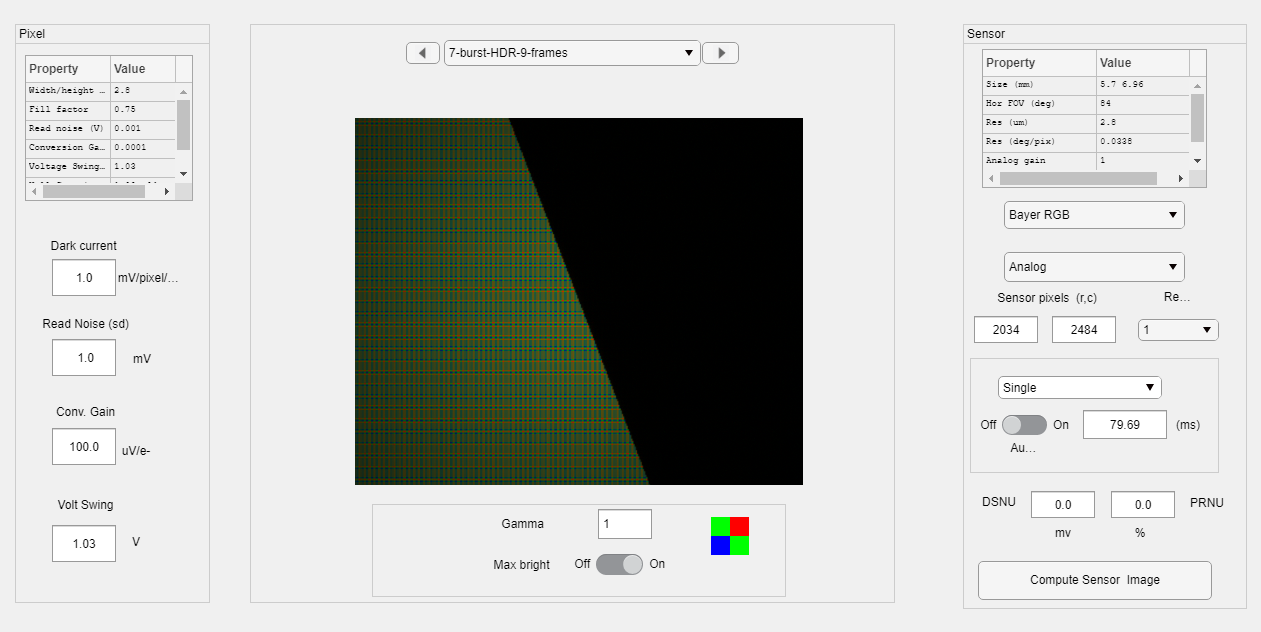

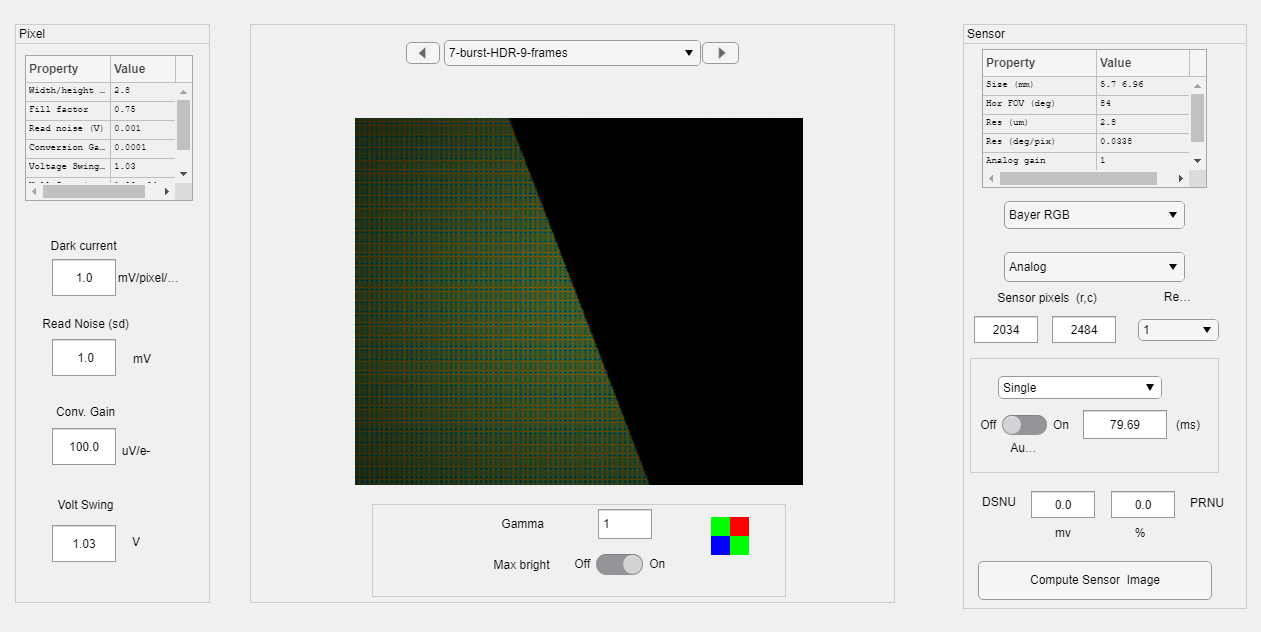

sensorHDRSum = sensorSet(sensorHDR,'exp time',hdrTiming(hdrImages + 1)); % set back
sensorHDRSum = sensorComputeMEV(sensorHDRSum, oi);
% ComputeMEV changes the sensor name, so we'll change it back
sensorHDRSum = sensorSet(sensorHDRSum,'name',sprintf('burst-HDR-%d-frames',numel(hdrTiming)));
voltsHDR = sensorGet(sensorHDRSum, 'volts');

sensorWindow(sensorHDRSum);

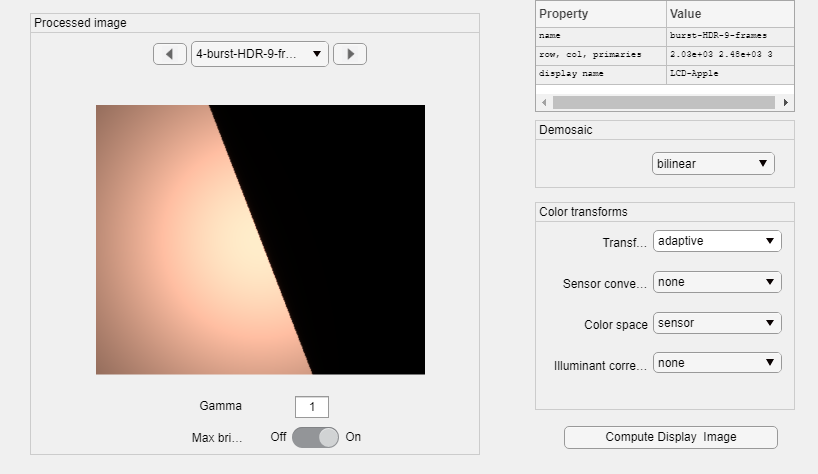

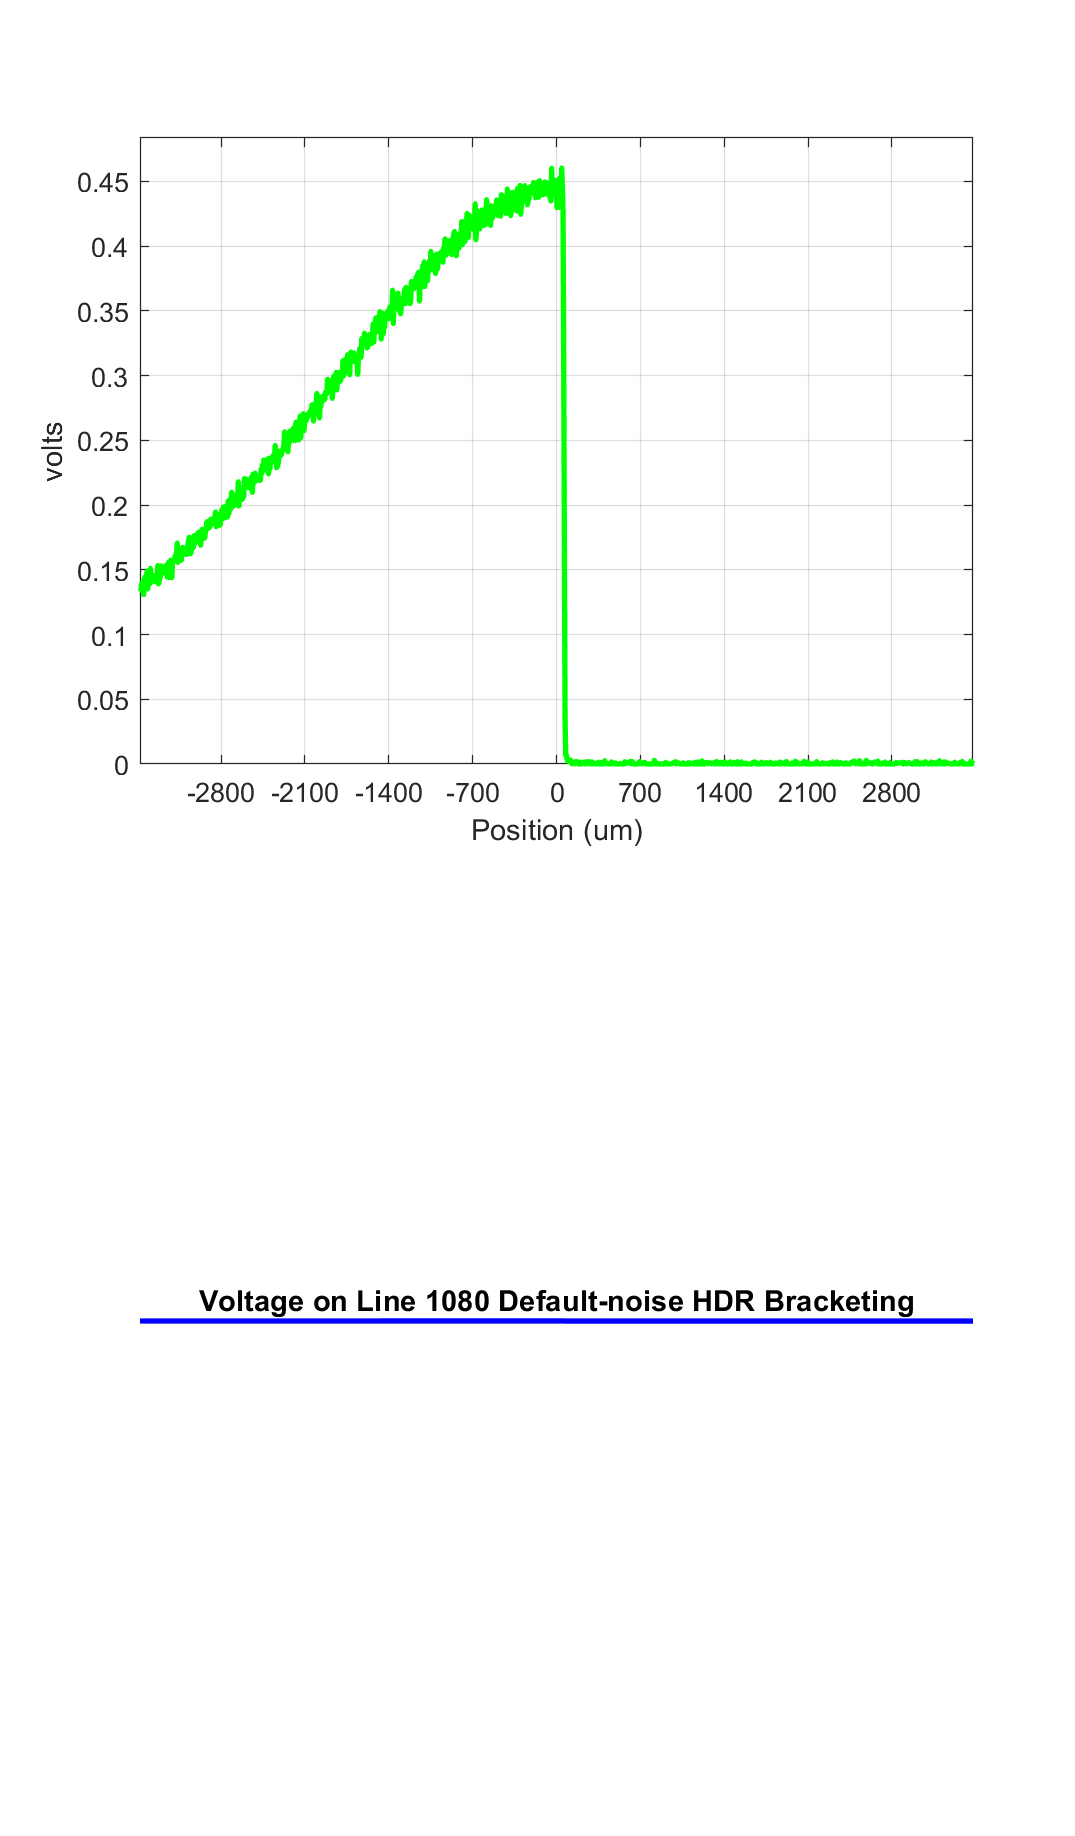

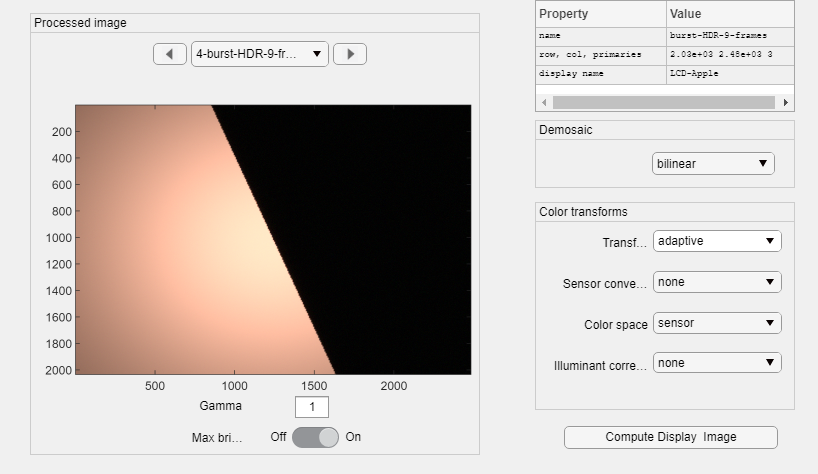


% Line is (x,y), not row,col.  (1,1) is upper left corner.
sensorPlot(sensorHDRSum,'volts hline',[1,showLine]);
title(['Voltage on Line ', num2str(showLine), ' Default-noise HDR Bracketing']);

ipHDR  = ipCreate;
ipHDR = ipSet(ipHDR, 'render demosaic only', 'true');
ipHDR  = ipCompute(ipHDR,sensorHDRSum);
if hdrScene
    rgbHDR = ipGet(ipHDR,'srgb');
    rgbHDR = hdrRender(rgbHDR);
    burstHDR = ieNewGraphWin;
    burstWin.Name = 'Bracketing with Default Noise';
    fprintf("Bracketing with Default Noise\n");
    imagescRGB(rgbHDR);
end
ipWindow(ipHDR);  


% Wonder if we still need this in Matlab 2020??
ieSessionSet('waitbar',wbState);  % Dealing with a waitbar/Matlab issue.

## Experiment with Scene and Camera Motion

We provide two different ways of generating motion. The simplest uses whichever scene you've already chosen and shifts it by random amounts in the x,y planes (with a maximum translation you set). This simulates translational movement of the camera. This may also be of interest when evaluating EIS sytems, as most of those used in smartphones currently (2020) only offer translational camera shifts.

You can also choose "3D Simulated", which relies on a series of pre-generated 3D scenes that include subject motion. Subject motion is important because while camera motion can often be addressed by a global alignment and transformation, subject motion only affects portions of a scene, and is typically harder to fix without artifacts.

For a quick comparison, run this script using the slanted edge target (one of the options at the top of the script). Then, in the IP Windows generated you can use the Analyze menu to look at the MTF for the various designs, and see the direct effect that camera motion has on the sharpness of a burst of images.

Read 11 materials
Read 3 textures
Reading C4D geometry information.
New light added.


Reading multispectral data with raw data.


Reading multispectral data with raw data.


Reading multispectral data with raw data.


Reading multispectral data with raw data.


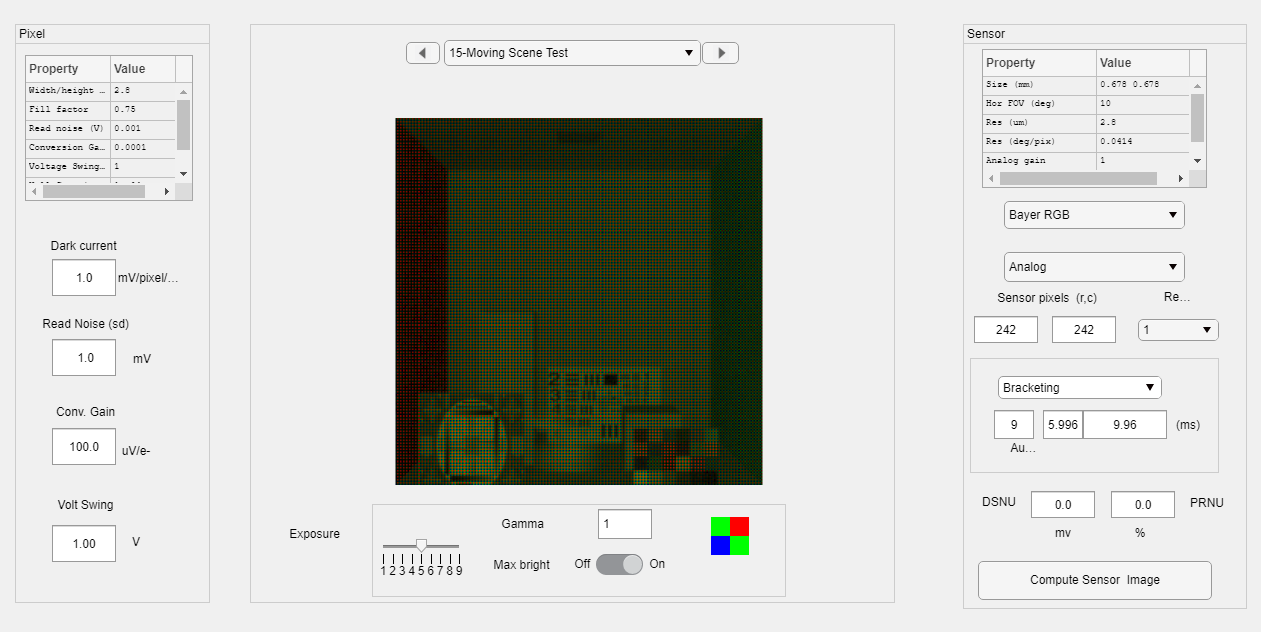

motionType = "3D Simulated";
% assume the same burst timing
sensorBurstMotion = sensorSet(sensor,'exp time',burstTiming(1)); 
sensorBurstMotion = sensorSet(sensorBurstMotion,'name','Moving Scene Test');
oi = oiCreate(); % default optics for now

if isequal(motionType, 'Artificial Translation') % Scene (Camera) translation only
    motionHDegrees = 2;
    motionVDegrees = 0.3;
    tScene = scene; % initial Seed
    % translation wants degrees
    motionArray = genMotion(motionHDegrees, motionVDegrees, numImages); % Set large to see effect
    sensorBurstMotion = sensorSet(sensorBurstMotion, 'exposure method', 'burst');
    
    for ii = 1:numImages
        % simple motion model where user tries to keep initial
        % position but is off by a random amount each time
        tScene = sceneTranslate(scene, motionArray(ii, :), sceneGet(scene, 'mean luminance'));
        sceneWindow(tScene);
        tOI = oiCompute(tScene, oi);
        % probably need to be more definitive about getting aspect ratios
        % to match
        if ii == 1
            sensorBurstMotion = sensorSet(sensorBurstMotion,'vfov',sceneGet(tScene,'vfov'),tOI);
        end
        % simple test with the Burst sensor
        tVolts = sensorGet(sensorBurstMotion, 'volts');
        tSensor = sensorCompute(sensorBurstMotion, tOI);
        % initialize or add to what we have so far
        if isempty(tVolts)
            sensorBurstMotion = sensorSet(sensorBurstMotion,'volts', sensorGet(tSensor,'volts'));
        else
            sensorBurstMotion = sensorSet(sensorBurstMotion,'volts', tVolts + sensorGet(tSensor,'volts'));
        end
    end
else % Subject motion or other elements incorporated into a series of 3D scenes
    
    sceneFiles = genSubjectMotionImages([],[],4);
    sensorSequence = [];
    for ii = 1:numel(sceneFiles)
        burstScene = sceneFromFile(sceneFiles(ii),'hyperspectral');
        burstOI = oiCompute(burstScene, oi);
        if ii == 1
            % only do this once, as otherwise it keeps resetting our
            % voltages!
            sensorBurstMotion = sensorSetSizeToFOV(sensorBurstMotion, [sceneGet(burstScene,'vfov'),sceneGet(burstScene, 'fov')], burstOI); % Seems to match better with our test data
        end
        
        % This is the original way where we just sum voltages
        % simple test with the Burst sensor
        %tempVolts = sensorGet(sensorBurstMotion, 'volts');
        %tempSensor = sensorCompute(sensorBurstMotion, burstOI);
        % initialize or add to what we have so far
        %if isempty(tempVolts)
        %    sensorBurstMotion = sensorSet(sensorBurstMotion,'volts', sensorGet(tempSensor,'volts'));
        %else
        %    sensorBurstMotion = sensorSet(sensorBurstMotion,'volts', tempVolts + sensorGet(tempSensor,'volts'));
        %end
        
        tempSensor = sensorCompute(sensorBurstMotion, burstOI);
        tempSensor = sensorSet(tempSensor, 'exposure method', 'burst');
        sensorWindow(tempSensor);
        sensorSequence = [sensorSequence tempSensor];
        
    end
    % set this here as ipCompute relies on it

end

% Let's see how we did:
% old: sensorWindow(sensorBurstMotion);

ipBurstMotion  = ipCreate;
ipBurstMotion = ipSet(ipBurstMotion, 'render demosaic only', 'true');
ipBurstMotion = ipSet(ipBurstMotion, 'combination method', 'sum');

% old ipBurstMotion  = ipCompute(ipBurstMotion,sensorBurstMotion);
ipBurstMotion = ipCompute(ipBurstMotion, sensorSequence);

Dot indexing is not supported for variables of this type.

Error in sensorGet (line 630)
                val = sensor.color.filterSpectra;

Error in sensorGet (line 671)
                val = size(sensorGet(sensor,'filterSpectra'),2);

Error in ipCompute>ipComputeSingle (<a href="matlab: opentoline('B:\iset\isetcam\imgproc\ipCompute.m',172,0)">line 172<

ipWindow(ipBurstMotion);

% Right now this barely needs to be a function, but we'll want
% to make it more versatile as we learn more about models for camera
% motion.
% genMotion(.5, 2, 7)

function [motionArray] = genMotion(xPixels, yPixels, numFrames)
    motionArray = 2 * (rand(numFrames, 2)-.5) .* repmat([xPixels yPixels], numFrames, 1);
end
% if we don't already have images with subject motion
% then we can generate them
% currently using the Cornell Box + Bunny
function [sceneFiles] = genSubjectMotionImages(scenePath, sceneName,numFrames)

    if ~exist('scenePath','var') || isempty(scenePath)
       scenePath = 'Cornell_BoxBunnyChart';
    end
    if ~exist('sceneName','var') || isempty(sceneName)
        sceneName = 'cornell box bunny chart';
    end
    if ~exist('numFrames','var') || numFrames == 0
        numFrames = 4;
    end
    motionX = 0; % near/far for the cornell box scene
    motionY = 0; % up/down
    motionZ = 1; % left/right
    
    % initialize our pbrt scene
    if ~piDockerExists, piDockerConfig; end
    %% Read Cornell Box
    thisR = piRecipeDefault('scene name', sceneName);

    % Modify the film resolution
    thisR.set('filmresolution', [512, 512]);

    %% Add new light
    thisR = piLightAdd(thisR,... 
        'type','point',...
        'light spectrum','Tungsten',...
        'cameracoordinate', true);
    
    % Find the bunny! (our default)
    bunnyName = 'Default'; % hopefully will get changed
    
    imageFolderPath = fullfile(isetRootPath, 'local', scenePath, 'images');
    if ~isfolder(imageFolderPath)
        mkdir(imageFolderPath);
    end
    sceneFiles = [];
    for ii = 1:numFrames
        imageFilePrefixName = fullfile(imageFolderPath, append("frame_", num2str(ii)));
        imageFileName = append(imageFilePrefixName,  ".mat");
        if ~isfile(imageFileName)
            moveX = motionX * (ii - 1);
            moveY = motionY * (ii - 1);
            moveZ = motionZ * (ii - 1);

            % if we want movement during each frame, need to get
            % the actual exposure time from the caller:
            thisR.set('cameraexposure', 0.5);

            % setting motion isn't working for me:
            thisR.set('asset', bunnyName, 'motion', 'rotation', [0 0 0], ...
                'translation', [moveX, moveY, moveZ]);
            % but translation does:
            %thisR.set('asset', bunnyName, 'translation', [moveX, moveY, moveZ]);

            %% Write recipe
            piWrite(thisR);

            %% Render and visualize
            [scene, results] = piRender(thisR, 'render type', 'radiance');
            sceneToFile(imageFileName,scene);
            sceneSaveImage(scene,imageFilePrefixName);
        end
        sceneFiles = [sceneFiles imageFileName]; %#ok<AGROW> 
    end
end